# Sign Perturbed sums

#### Data generator

% Define ARX model parameters
% y(t) - 0.44 y(t-1) = 0.33u(t-1) + 1e(t) 
% u(t) = 0.31 y(t) + 0.23 y(t-1) controller
theta_real = [-0.44, 0.33]

theta_real =    -0.4400    0.3300


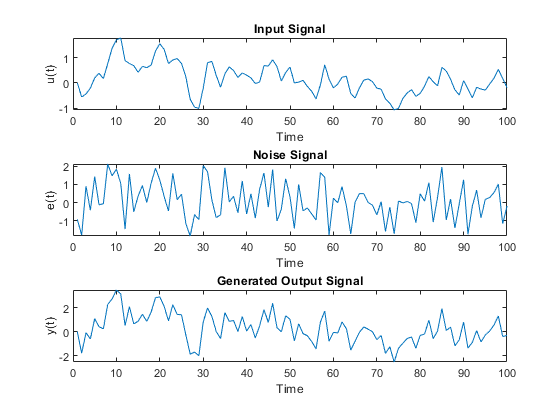

A = [1, theta_real(1)];   % AR coefficients
B = [theta_real(2)];       % MA coefficients
C = [1];       % input coefficients
D = 0;           % Constant term
noiseVar = 1;  % Variance of the noise

% Create an instance of ARMAXGenerator
armaxGen = ARMAXGenerator(A, B, C, D, @custom_past_y);

% Generate data
n = 100; % Number of data points
e = sqrt(noiseVar) * randn(n, 1); % Noise sequence
[y, u, e] = armaxGen.generateData(n,e);
% Plot the generated data
armaxGen.plotData(y, u, e);

SPS

% Define confidence probability and number of random signs
% Define SPS parameters
m = 100;   % Integer m
q = 5;    % Integer q 
p = 1-q/m %Confidence probability p = 1 − q/m

p = 0.9500

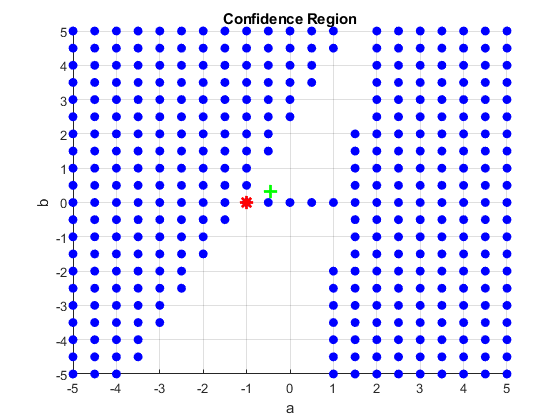


X = createFeatureMatrix(y,u);

% Create an instance of SPS
sps = SPS(p, m, q, n);
theta_le = sps.estimateParameters(X,y);
% Generate random signs and permutation
conf_region = [];  % Initialize an empty array to store the confidence region points

for a = -5:0.5:5
    for b = -5:0.5:5
        sps = sps.generateRandomSignsAndPermutation();
        theta_hat = [a; b];  % Create a column vector [a; b]
        % Check the condition using the sps_indicator function
        if sps.sps_indicator(y, u, theta_hat, @custom_past_y, @createFeatureMatrix) == 1
            % Add the pair [a, b] to conf_region
            conf_region = [conf_region; a, b];
        end
    end
end


% Plot the confidence region
if ~isempty(conf_region)
    figure;  % Create a new figure
    hold on 
    plot(conf_region(:, 1), conf_region(:, 2), 'bo', 'MarkerFaceColor', 'b');
    plot(theta_le(1), theta_le(2), 'r*', 'MarkerSize', 10, 'LineWidth', 2);  % Add the point theta
    plot(theta_real(1), theta_real(2), 'g+', 'MarkerSize', 10, 'LineWidth', 2);  % Add the point theta
    hold off    
    xlabel('a');  % Label for the x-axis
    ylabel('b');  % Label for the y-axis
    title('Confidence Region');
    grid on;  % Turn on the grid
else
    disp('No points in the confidence region.');
end

Aux function

function u_out = step_controller(y,u,t)
    if t > 10
        u_out = 1;
    else
        u_out = 0;
    end  
end

function u_out = custom_past_y(y,u,t)
    d = 0.31;
    e = 0.23;
    u_out = d * y(t);
    if t-1 > 0
        u_out = u_out + e * y(t-1);
    end
end

function X = createFeatureMatrix(y, u)
    % Ensure y and u have the same length
    if length(y) ~= length(u)
        error('Vectors y and u must have the same length.');
    end
    
    % Number of data points
    N = length(y);
    
    % Initialize the feature matrix X
    % X will have (N) rows and 2 columns corresponding to [-y(t-1), u(t-1)]
    X = zeros(N, 2);
    
    % Fill the feature matrix
    for t = 2:N
        X(t-1, :) = get_phi(y,u,t);
    end
end

function phi = get_phi(y, u, t)
    phi = [-y(t-1), u(t-1)];
end
